clc, close, clear all


load finger_ischaemia.mat

% Convert the images from RGB to Y component and store it
Y = rgb2y(finger1_normal);
Y = imresize(Y, 0.25);

Y2 = rgb2y(finger2_normal);
Y2 = imresize(Y2, 0.25);

Y3 = rgb2y(finger3_normal);
Y3 = imresize(Y3, 0.25);

spectrum_height = size(Y, 1);

spectrum_height = 612

spectrum_length = size(Y,2);

spectrum_length = 816


figure
imshow(Y)

% Construct synthetic hypercube with different spectrogram

% Initialize an empty array for the synthetic hypercube
syn_hcube = zeros(spectrum_height, spectrum_height, spectrum_length);

% Randomly select between Y, Y2, and Y3 for each slice in the third dimension
for i = 1:816
    choice = randi([1, 3]); % Randomly select a number between 1 and 3
    switch choice
        case 1
            slice = Y;
        case 2
            slice = Y2;
        case 3
            slice = Y3;
    end
    % Fill the i-th slice in the second dimension with the selected image
    syn_hcube(:, i, :) = permute(slice, [1, 3, 2]);
end


% Calibrate the spectrogram wavelengths
load pure_colours.mat

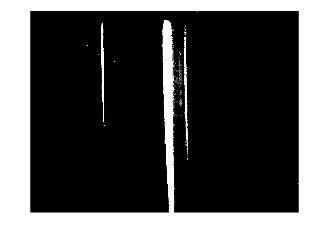


%% displaying hyperspectral image through hypercube
wavelength = linspace(0.28, 1.0, spectrum_length); % calibrate this

hcube = hypercube(syn_hcube, wavelength);
img = colorize(hcube,'Method', 'rgb', 'ContrastStretching', true);


figure
imshow(img)

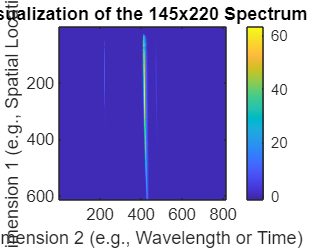

figure; % Create a new figure window
imagesc(Y);
colorbar; % Add a colorbar to indicate the scale of values
xlabel('Dimension 2 (e.g., Wavelength or Time)');
ylabel('Dimension 1 (e.g., Spatial Locations)');
title('Visualization of the 145x220 Spectrum');

slice = syn_hcube(:,20,:)

slice = slice(:,:,1) =

     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
   

slice = squeeze(slice)

slice =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     

Convert RGB into just Y component of YUV

function Y = rgb2y(RGB)
    % Transformation matrix to get Y component
    transformMat = [0.299, 0.587, 0.114];
    % Apply the matrix to each pixel
    Y = double(RGB(:,:,1)) * transformMat(1) + double(RGB(:,:,2)) * transformMat(2) + double(RGB(:,:,3)) * transformMat(3);
end